# Task 3.1

clc;
clear;
close all;

## Aproximate the probability dense with the Kernel

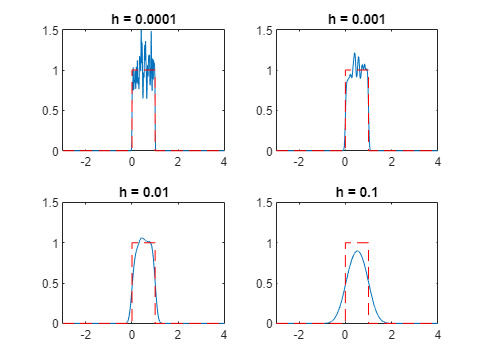

syms var;
rect = rectangularPulse(0,1,var); % Create a rectangular pulse for ploting

sz = [1 1000]; % Set the amount of implementations
samples = 4 * sz(2); % Set the number of the samples for x axis

x = rand(sz); % Generate random implementations in range [0, 1] 
x_axis = linspace(-3, 4, samples); % The x axis values
x = x_axis' - x; % Calculate the value for the kernel

hi = [0.0001 0.001 0.01 0.1]; % Set the values for h

for i=1:size(hi,2)
    h = hi(i);
    f_hat = mean(gaussianKernel(x,h), 2); % Aproximate the probability dense with the Kernel
    %===========PLOT==========%
    subplot(2,2,i)
    plot(x_axis, f_hat)
    hold on;
    fplot(rect, 'r--')
    title(['h = ' num2str(h)])
    axis([-3 4 0 1.5])
    %=========================%
end

## Functions

function prob_dens = gaussianKernel(x,h) %Gaussian Kernel
    prob_dens = exp(-0.5 * (x.^2) / h) / (sqrt(2*pi*h)) ;
end